# Epipolar geometry

We have introduced stereopsis and said that from a specific setup of known geometry (namely, two cameras aligned pointing the same direction and just translated on the $x$ axis by a certain distance $b$ called *baseline*) we can calculate a certain 3D point given at least two images that captured it taken from different cameras. Now we want to extend this notion in order to utilize any geometry of the setup: given two images, we compute a **rectification** of them, practically pivoting the cameras over their respective center points and "retaking" the images, which now will be aligned as needed. The problem now is the following: how can we know the exact amount of "pivoting" needed by each camera in order to point in the same direction? We need to introduce **epipolar geometry**.

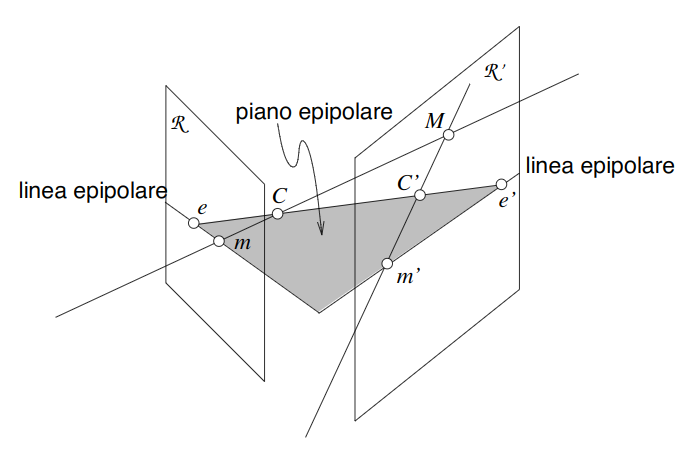

In epipolar geometry we study **epipoles**, which are the projections of one center point onto the other image (taken from the other camera of course), and conseguently we study the relationship between couples of **conjugated points** $(m, m')$ belonging to different images, which are points that are the projections of a common scene point $M$ but in two different images. 

Conceptually, given a point $m \in I_1$ s.t. $m \simeq PM$, every 3D point on its optic ray (which is by definition the line passing throught $m$ and $C$) is projected onto $I_2$, tracing the **epipolar line of **$m$** onto **$C'$ (the same can be done for any point $m'$, tracing the *epipolar line of *$m'$* onto *$C$); in each optic ray is contained the center point $C$, which will always be projected onto $I_2$ as the same point $e'$, to which we give the name of **epipole of **$C$** onto **$C'$. From this, we will see that two points $(m, m')$ are conjugated iff $m$ lies onto the epipolar line of $m'$ onto $C$ and viceversa.

% adds calibration results and project.mlx
addpath('../0.utils');

calib_results_folder = '../0.calib_results';

% load images and calibrations
left_camera_calib.file = fullfile(calib_results_folder, 'calib-cube-img_2.mat');
[~, left_camera_calib.filename, ~] = fileparts(left_camera_calib.file);
left_camera_calib.filename = split(left_camera_calib.filename, '-');
left_camera_calib.subject = left_camera_calib.filename{2};
left_camera_calib.img = left_camera_calib.filename{3};

right_camera_calib.file = fullfile(calib_results_folder, 'calib-cube-img_1.mat');
[~, right_camera_calib.filename, ~] = fileparts(right_camera_calib.file);
right_camera_calib.filename = split(right_camera_calib.filename, '-');
right_camera_calib.subject = right_camera_calib.filename{2};
right_camera_calib.img = right_camera_calib.filename{3};

if ~strcmp(left_camera_calib.subject, right_camera_calib.subject)
    error('Calibrations must be taken from the same object');
end

if strcmp(left_camera_calib.img, right_camera_calib.img)
    error('Calibrations must be unique (same calibration twice was given)');
end

% everything's ok, prepare the stereo result path
stereo_setup_file = sprintf('stereo-%s-%s+%s.mat', ...
    left_camera_calib.subject, left_camera_calib.img, right_camera_calib.img);
stereo_setup_path = fullfile(calib_results_folder, stereo_setup_file);

stereo.L_camera = load(left_camera_calib.file);
stereo.R_camera = load(right_camera_calib.file);


% compute the fundamental matrix
stereo.setup = fundamental(stereo.L_camera.P, stereo.R_camera.P);


% save setup
save(stereo_setup_path, '-struct', 'stereo');

clear calib_results_folder left_camera_calib right_camera_calib stereo_setup_file stereo_setup_path;

## Test the epipolar setup

After having created the epipolar setup, we place the two images one next to the other and, given a point from one of the two, we plot the epipole line onto the other.

% load if just created the setup
if exist('stereo','var') == 0
    % otherwise set the desired setup
    stereo = load('../0.calib_results/stereo-cube-img_2+img_1.mat');
end

show_epipolar_lines(stereo);